p0 = [-0.24 -0.24 0.72]';
pDes = [0.24 0.24]';
q_util = [-0.32, -0.78, -2.56, -1.63, -1.57, 3.49]';

T0 = [eye(3) p0; 0 0 0 1];

q0 = LM_method(T0, q_util);

threshold = 0.001;
qk = q0;
i=0;
dt = 0.001;

res = [];

while(true)
    i = i+1;
    [pCur, ~] = ur5Direct(qk);
    pCur = [pCur(1) pCur(2)]';

    res = [res; pCur'];

    e_k = pDes - pCur;
    
    e_norm = norm(e_k);
    if(e_norm < threshold)
        break;
    end
    qk = computeNext(qk, pDes, i, dt);
 
end
i

i = 6896

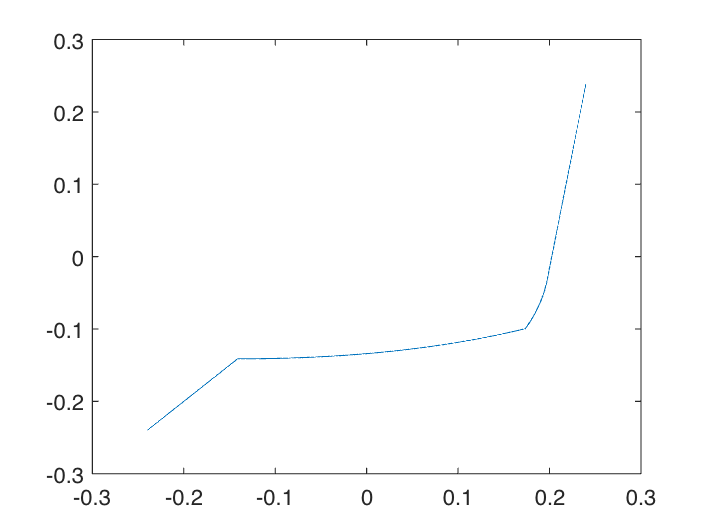

x = res(:, 1);
y = res(:, 2);

plot(x,y)

x = [-1.5 : 0.01 : 1.5];
y = [-1.5 : 0.01 : 1.5];
mat = [x;y];

hold on;
for i = 1:length(x)
       z = mypotential(mat(:,i), [0.24 0.24]');
       plot3(x(i),y(i),z)

end
hold off;

function U = mypotential(p_cur, p_end)
r0 = 0.2;

if(sqrt(p_cur(1).^2 + p_cur(2).^2) > r0)
    U = [0 0]';
else
    m = sign(p_end(1) - p_cur(1));
    x = sqrt(1 ./ (m.^2 +1));
    y = m * x;
    U = [x y]';
end

end